%% Define the numerator and denominator of the transfer function
num = [2 1]; % Numerator coefficients of '2s+1'
den = conv([1 0], conv([1 1], [1 2])); % Denominator coefficients of 's(s+1)(s+2)'

% Create the transfer function model
sys = tf(num, den)

sys =
 
       2 s + 1
  -----------------
  s^3 + 3 s^2 + 2 s
 
Continuous-time transfer function.
Model Properties


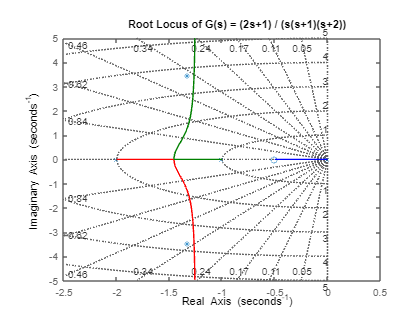


% Generate and plot the root locus
figure;
rlocus(sys);
hold on
points = [-1.33+3.47j, -1.33-3.47j]; % Points to mark on the root locus plot
plot(points, '*'); % Plotting points on the root locus plot
title('Root Locus of G(s) = (2s+1) / (s(s+1)(s+2))');
xlabel('Real Axis');
ylabel('Imaginary Axis');
grid on; 
hold off


% Display poles and zeros of the system
pole(sys)

ans =      0
    -2
    -1


zero(sys)

ans = -0.5000


% Calculate damping ratio (zetha) and natural frequency (Wn)
Mp = log(0.3); % Desired percentage overshoot in logarithm form
zetha = -Mp/sqrt(Mp^2 + pi^2) % Damping ratio calculation

zetha = 0.3579

tp = 3; % Desired settling time
Wn = 4/(tp*zetha) % Natural frequency calculation

Wn = 3.7259

beta = acos(zetha); % Angle beta calculation
betaa = rad2deg(beta) % Convert angle beta to degrees

betaa = 69.0313


% Calculate gains for different compensators
s = -1.33 + 3.47j; % Point in the complex plane for compensator calculations
num0 = (2*s+1); % Numerator of the original transfer function at point s
den0 = s*(s+1)*(s+2); % Denominator of the original transfer function at point s

% Calculating gains K for different compensators
num_A = num0 * (s+2);
den_A = den0 * (s+2.13);
K_A = abs(den_A / num_A)

K_A = 6.4642


num_B = num0 * (s+1.5);
den_B = den0 * (s+1.62);
K_B = abs(den_B / num_B)

K_B = 6.4299


num_C = num0 * (s+2.5);
den_C = den0 * (s+2.64);
K_C = abs(den_C / num_C)

K_C = 6.4978


num_D = num0 * (s+3.63);
den_D = den0 * (s+3.81);
K_D = abs(den_D / num_D)

K_D = 6.5726


% Create open-loop systems with compensators
sys_0 = tf(1.2*num, den) % Open-loop system with initial gain adjustment

sys_0 =
 
     2.4 s + 1.2
  -----------------
  s^3 + 3 s^2 + 2 s
 
Continuous-time transfer function.
Model Properties


sys_A = tf(K_A*[2 1], [1 3.13 2.13 0]) % Open-loop system with compensator A

sys_A =
 
      12.93 s + 6.464
  -----------------------
  s^3 + 3.13 s^2 + 2.13 s
 
Continuous-time transfer function.
Model Properties


sys_B = tf(K_B*[2 4 1.5], [1 4.62 6.86 3.24 0]) % Open-loop system with compensator B

sys_B =
 
     12.86 s^2 + 25.72 s + 9.645
  ----------------------------------
  s^4 + 4.62 s^3 + 6.86 s^2 + 3.24 s
 
Continuous-time transfer function.
Model Properties


sys_C = tf(K_C*[2 6 2.5], [1 5.64 9.92 5.28 0]) % Open-loop system with compensator C

sys_C =
 
       13 s^2 + 38.99 s + 16.24
  ----------------------------------
  s^4 + 5.64 s^3 + 9.92 s^2 + 5.28 s
 
Continuous-time transfer function.
Model Properties


sys_D = tf(K_D*[2 8.26 3.63], [1 6.81 13.43 7.62 0]) % Open-loop system with compensator D

sys_D =
 
      13.15 s^2 + 54.29 s + 23.86
  -----------------------------------
  s^4 + 6.81 s^3 + 13.43 s^2 + 7.62 s
 
Continuous-time transfer function.
Model Properties



% Create closed-loop systems with unit feedback
cl_sys_0 = feedback(sys_0, 1); % Closed-loop system with initial gain adjustment
cl_sys_A = feedback(sys_A, 1); % Closed-loop system with compensator A
cl_sys_B = feedback(sys_B, 1); % Closed-loop system with compensator B
cl_sys_C = feedback(sys_C, 1); % Closed-loop system with compensator C
cl_sys_D = feedback(sys_D, 1); % Closed-loop system with compensator D
cl_sys = feedback(sys, 1);% Closed-loop Main system

% Time vector for simulation
t = 0:0.01:10;

%% Step responses
[y_0, t_0] = step(cl_sys_0, t); % Step response of closed-loop system with initial gain adjustment
[y_A, t_A] = step(cl_sys_A, t); % Step response of closed-loop system with compensator A
[y_B, t_B] = step(cl_sys_B, t); % Step response of closed-loop system with compensator B
[y_C, t_C] = step(cl_sys_C, t); % Step response of closed-loop system with compensator C
[y_D, t_D] = step(cl_sys_D, t); % Step response of closed-loop system with compensator D
[y, t] = step(cl_sys, t);% Step response of closed-loop Main system

% Display step information
info_0 = stepinfo(cl_sys_0, 'SettlingTimeThreshold', 0.02) % Step information of closed-loop system with initial gain adjustment

info_0 = struct with fields:
         RiseTime: 3.6800
    TransientTime: 8.7277
     SettlingTime: 8.7277
      SettlingMin: 0.9003
      SettlingMax: 0.9998
        Overshoot: 0
       Undershoot: 0
             Peak: 0.9998
         PeakTime: 22.1264


info_A = stepinfo(cl_sys_A) % Step information of closed-loop system with compensator A

info_A = struct with fields:
         RiseTime: 0.4016
    TransientTime: 3.6489
     SettlingTime: 3.6489
      SettlingMin: 0.8867
      SettlingMax: 1.2334
        Overshoot: 23.3444
       Undershoot: 0
             Peak: 1.2334
         PeakTime: 0.8996


info_B = stepinfo(cl_sys_B) % Step information of closed-loop system with compensator B

info_B = struct with fields:
         RiseTime: 0.4030
    TransientTime: 3.6993
     SettlingTime: 3.6993
      SettlingMin: 0.8855
      SettlingMax: 1.2304
        Overshoot: 23.0399
       Undershoot: 0
             Peak: 1.2304
         PeakTime: 0.9014


info_C = stepinfo(cl_sys_C) % Step information of closed-loop system with compensator C

info_C = struct with fields:
         RiseTime: 0.4001
    TransientTime: 3.6105
     SettlingTime: 3.6105
      SettlingMin: 0.8869
      SettlingMax: 1.2364
        Overshoot: 23.6383
       Undershoot: 0
             Peak: 1.2364
         PeakTime: 0.8997


info_D = stepinfo(cl_sys_D) % Step information of closed-loop system with compensator D

info_D = struct with fields:
         RiseTime: 0.3978
    TransientTime: 2.3797
     SettlingTime: 2.3797
      SettlingMin: 0.8867
      SettlingMax: 1.2403
        Overshoot: 24.0295
       Undershoot: 0
             Peak: 1.2403
         PeakTime: 0.9004


info = stepinfo(cl_sys) % Step information of closed-loop Main system

info = struct with fields:
         RiseTime: 4.5641
    TransientTime: 9.9974
     SettlingTime: 9.9974
      SettlingMin: 0.9003
      SettlingMax: 0.9983
        Overshoot: 0
       Undershoot: 0
             Peak: 0.9983
         PeakTime: 17.7866


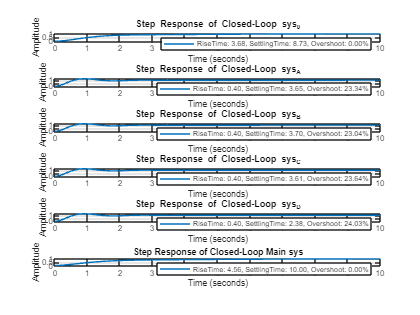


% Display step response plots
figure;
subplot(6,1,1);
plot(t_0, y_0);
grid on;
title('Step Response of Closed-Loop sys_0');
xlabel('Time (seconds)');
ylabel('Amplitude');
legend(sprintf('RiseTime: %.2f, SettlingTime: %.2f, Overshoot: %.2f%%', info_0.RiseTime, info_0.SettlingTime, info_0.Overshoot));

subplot(6,1,2);
plot(t_A, y_A);
grid on;
title('Step Response of Closed-Loop sys_A');
xlabel('Time (seconds)');
ylabel('Amplitude');
legend(sprintf('RiseTime: %.2f, SettlingTime: %.2f, Overshoot: %.2f%%', info_A.RiseTime, info_A.SettlingTime, info_A.Overshoot));

subplot(6,1,3);
plot(t_B, y_B);
grid on;
title('Step Response of Closed-Loop sys_B');
xlabel('Time (seconds)');
ylabel('Amplitude');
legend(sprintf('RiseTime: %.2f, SettlingTime: %.2f, Overshoot: %.2f%%', info_B.RiseTime, info_B.SettlingTime, info_B.Overshoot));

subplot(6,1,4);
plot(t_C, y_C);
grid on;
title('Step Response of Closed-Loop sys_C');
xlabel('Time (seconds)');
ylabel('Amplitude');
legend(sprintf('RiseTime: %.2f, SettlingTime: %.2f, Overshoot: %.2f%%', info_C.RiseTime, info_C.SettlingTime, info_C.Overshoot));

subplot(6,1,5);
plot(t_D, y_D);
grid on;
title('Step Response of Closed-Loop sys_D');
xlabel('Time (seconds)');
ylabel('Amplitude');
legend(sprintf('RiseTime: %.2f, SettlingTime: %.2f, Overshoot: %.2f%%', info_D.RiseTime, info_D.SettlingTime, info_D.Overshoot));

subplot(6,1,6);
plot(t, y);
grid on;
title('Step Response of Closed-Loop Main sys');
xlabel('Time (seconds)');
ylabel('Amplitude');
legend(sprintf('RiseTime: %.2f, SettlingTime: %.2f, Overshoot: %.2f%%', info.RiseTime, info.SettlingTime, info.Overshoot));

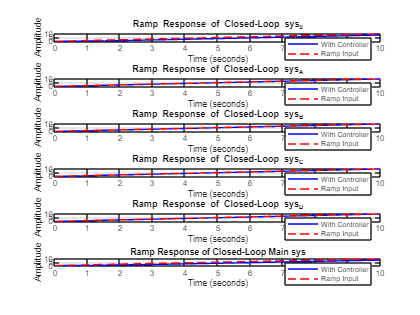


%% Ramp input response

% Define the ramp input signal
ramp_input = t; % Ramp input signal over time

% Simulate ramp response for closed-loop sys_0
[y_r0, t_r0] = lsim(cl_sys_0, ramp_input, t); % Simulate response using lsim
figure;
subplot(6,1,1);
plot(t_r0, y_r0, 'b', t_r0, ramp_input, 'r--'); % Plot system response and ramp input
legend('With Controller', 'Ramp Input');
grid on;
title('Ramp Response of Closed-Loop sys_0');
xlabel('Time (seconds)');
ylabel('Amplitude');

% Simulate ramp response for closed-loop sys_A
[y_rA, t_rA] = lsim(cl_sys_A, ramp_input, t); % Simulate response using lsim
subplot(6,1,2);
plot(t_rA, y_rA, 'b', t_rA, ramp_input, 'r--'); % Plot system response and ramp input
legend('With Controller', 'Ramp Input');
grid on;
title('Ramp Response of Closed-Loop sys_A');
xlabel('Time (seconds)');
ylabel('Amplitude');

% Simulate ramp response for closed-loop sys_B
[y_rB, t_rB] = lsim(cl_sys_B, ramp_input, t); % Simulate response using lsim
subplot(6,1,3);
plot(t_rB, y_rB, 'b', t_rB, ramp_input, 'r--'); % Plot system response and ramp input
legend('With Controller', 'Ramp Input');
grid on;
title('Ramp Response of Closed-Loop sys_B');
xlabel('Time (seconds)');
ylabel('Amplitude');

% Simulate ramp response for closed-loop sys_C
[y_rC, t_rC] = lsim(cl_sys_C, ramp_input, t); % Simulate response using lsim
subplot(6,1,4);
plot(t_rC, y_rC, 'b', t_rC, ramp_input, 'r--'); % Plot system response and ramp input
legend('With Controller', 'Ramp Input');
grid on;
title('Ramp Response of Closed-Loop sys_C');
xlabel('Time (seconds)');
ylabel('Amplitude');

% Simulate ramp response for closed-loop sys_D
[y_rD, t_rD] = lsim(cl_sys_D, ramp_input, t); % Simulate response using lsim
subplot(6,1,5);
plot(t_rD, y_rD, 'b', t_rD, ramp_input, 'r--'); % Plot system response and ramp input
legend('With Controller', 'Ramp Input');
grid on;
title('Ramp Response of Closed-Loop sys_D');
xlabel('Time (seconds)');
ylabel('Amplitude');

% Simulate ramp response for closed-loop Main sys 
[y_r, t_r] = lsim(cl_sys, ramp_input, t); % Simulate response using lsim
subplot(6,1,6);
plot(t_r, y_r, 'b', t_r, ramp_input, 'r--'); % Plot system response and ramp input
legend('With Controller', 'Ramp Input');
grid on;
title('Ramp Response of Closed-Loop Main sys');
xlabel('Time (seconds)');
ylabel('Amplitude');

% Define the transfer function G(s) = 1 / (1 + 1.34s)
numerator = 1; % Numerator of the transfer function
denominator = [1 1.34]; % Denominator of the transfer function
G = tf(numerator, denominator); % Create transfer function G(s)

% Define the delay
delay = 0.2; % Time delay in seconds

% Pade approximation for the delay
[num_delay, den_delay] = pade(delay, 1); % 1st-order Pade approximation
Delay_approx = tf(num_delay, den_delay); % Create transfer function for delay approximation

% Combine transfer function with delay approximation
G_with_delay = series(G, Delay_approx); % Series combination of G(s) and delay

% Define controllers
% P Controller
Kp1 = 1.34 / 0.2; % Proportional gain for P controller
Gc1 = Kp1; % Transfer function of P controller

% PI Controller
Kp2 = 0.9 * Kp1; % Proportional gain for PI controller
Ti2 = 0.2 / 0.3; % Integral time constant for PI controller
Gc2 = Kp2 * (1 + tf(1, [Ti2 0])); % Transfer function of PI controller

% PID Controller
Kp3 = 1.2 * Kp1; % Proportional gain for PID controller
Ti3 = 2 * 0.2; % Integral time constant for PID controller
Td3 = 0.5 * 0.2; % Derivative time constant for PID controller
Gc3 = Kp3 * (1 + tf([Td3 0], 1) + tf(1, [Ti3 0])); % Transfer function of PID controller

% Closed-loop transfer functions
T1 = feedback(Gc1 * G_with_delay, 1); % Closed-loop transfer function with P controller
T2 = feedback(Gc2 * G_with_delay, 1); % Closed-loop transfer function with PI controller
T3 = feedback(Gc3 * G_with_delay, 1); % Closed-loop transfer function with PID controller

% Time vector for simulation
t = 0:0.01:10; % Time vector for simulation, from 0 to 10 seconds with 0.01 second steps

% Step responses
[y1, t1] = step(T1, t); % Step response of system with P controller
[y2, t2] = step(T2, t); % Step response of system with PI controller
[y3, t3] = step(T3, t); % Step response of system with PID controller

% Display step information (2% settling time criteria)
info_T1 = stepinfo(T1, 'SettlingTimeThreshold', 0.02) % Step response information for P controller

info_T1 = struct with fields:
         RiseTime: 0.1033
    TransientTime: 1.6383
     SettlingTime: 1.6586
      SettlingMin: 0.6355
      SettlingMax: 1.2922
        Overshoot: 55.0678
       Undershoot: 27.4233
             Peak: 1.2922
         PeakTime: 0.4367


info_T2 = stepinfo(T2, 'SettlingTimeThreshold', 0.02) % Step response information for PI controller

info_T2 = struct with fields:
         RiseTime: 0.1233
    TransientTime: 1.9139
     SettlingTime: 2.2700
      SettlingMin: 0.7542
      SettlingMax: 1.5755
        Overshoot: 57.5510
       Undershoot: 22.1497
             Peak: 1.5755
         PeakTime: 0.4882


info_T3 = stepinfo(T3, 'SettlingTimeThreshold', 0.02) % Step response information for PID controller

info_T3 = struct with fields:
         RiseTime: 0.1003
    TransientTime: 0.6171
     SettlingTime: 1.0210
      SettlingMin: 0.9014
      SettlingMax: 1.1281
        Overshoot: 12.8098
       Undershoot: 410.2041
             Peak: 4.1020
         PeakTime: 0


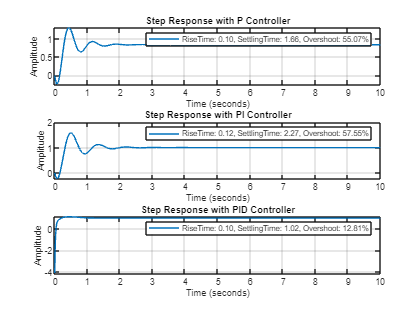


% Plot the step responses
figure;
subplot(3,1,1);
plot(t1, y1); % Plot step response of P controller
grid on;
title('Step Response with P Controller');
xlabel('Time (seconds)');
ylabel('Amplitude');
legend(sprintf('RiseTime: %.2f, SettlingTime: %.2f, Overshoot: %.2f%%', info_T1.RiseTime, info_T1.SettlingTime, info_T1.Overshoot));

subplot(3,1,2);
plot(t2, y2); % Plot step response of PI controller
grid on;
title('Step Response with PI Controller');
xlabel('Time (seconds)');
ylabel('Amplitude');
legend(sprintf('RiseTime: %.2f, SettlingTime: %.2f, Overshoot: %.2f%%', info_T2.RiseTime, info_T2.SettlingTime, info_T2.Overshoot));

subplot(3,1,3);
plot(t3, y3); % Plot step response of PID controller
grid on;
title('Step Response with PID Controller');
xlabel('Time (seconds)');
ylabel('Amplitude');
legend(sprintf('RiseTime: %.2f, SettlingTime: %.2f, Overshoot: %.2f%%', info_T3.RiseTime, info_T3.SettlingTime, info_T3.Overshoot));


%% Confirming the steady-state value
steady_state_value = dcgain(G);
disp(['Steady-state value of the plant G: ', num2str(steady_state_value)]);

Steady-state value of the plant G: 0.74627



%% Confirming the steady-state value of the controllers
steady_state_value1 = dcgain(feedback(Gc1 * G_with_delay, 1));
disp(['Steady-state value with P Controller: ', num2str(steady_state_value1)]);

Steady-state value with P Controller: 0.83333



steady_state_value2 = dcgain(feedback(Gc2 * G_with_delay, 1));
disp(['Steady-state value with PI Controller: ', num2str(steady_state_value2)]);

Steady-state value with PI Controller: 1



steady_state_value3 = dcgain(feedback(Gc3 * G_with_delay, 1));
disp(['Steady-state value with PID Controller: ', num2str(steady_state_value3)]);

Steady-state value with PID Controller: 1


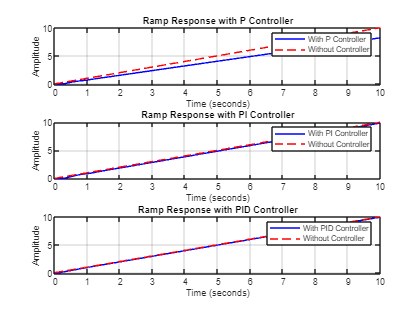

%% Ramp input response
ramp_input = t; % Ramp input signal over time 't'

% Ramp response for T1 (P Controller)
[y_r1, t_r1] = lsim(T1, ramp_input, t); % Simulate ramp response with T1 (P Controller)
[y_r1_sys, t_r1_sys] = lsim(G_with_delay, ramp_input, t); % Simulate ramp response without controller
figure;
subplot(3,1,1);
plot(t_r1, y_r1, 'b', t_r1_sys, ramp_input, 'r--'); % Plot ramp response for T1
legend('With P Controller', 'Without Controller');
grid on;
title('Ramp Response with P Controller');
xlabel('Time (seconds)');
ylabel('Amplitude');

% Ramp response for T2 (PI Controller)
[y_r2, t_r2] = lsim(T2, ramp_input, t); % Simulate ramp response with T2 (PI Controller)
[y_r2_sys, t_r2_sys] = lsim(G_with_delay, ramp_input, t); % Simulate ramp response without controller
subplot(3,1,2);
plot(t_r2, y_r2, 'b', t_r2_sys, ramp_input, 'r--'); % Plot ramp response for T2
legend('With PI Controller', 'Without Controller');
grid on;
title('Ramp Response with PI Controller');
xlabel('Time (seconds)');
ylabel('Amplitude');

% Ramp response for T3 (PID Controller)
[y_r3, t_r3] = lsim(T3, ramp_input, t); % Simulate ramp response with T3 (PID Controller)
[y_r3_sys, t_r3_sys] = lsim(G_with_delay, ramp_input, t); % Simulate ramp response without controller
subplot(3,1,3);
plot(t_r3, y_r3, 'b', t_r3_sys, ramp_input, 'r--'); % Plot ramp response for T3
legend('With PID Controller', 'Without Controller');
grid on;
title('Ramp Response with PID Controller');
xlabel('Time (seconds)');
ylabel('Amplitude');

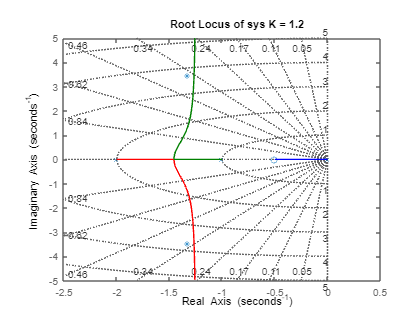


%% Root locus plots

% Root locus plot for sys_0 (Controller with K = 1.2)
figure;
rlocus(sys_0);
hold on
points = [-1.33+3.47j, -1.33-3.47j]; % Points to mark on the root locus plot
plot(points, '*');
title('Root Locus of sys K = 1.2');
xlabel('Real Axis');
ylabel('Imaginary Axis');
grid on; 
hold off

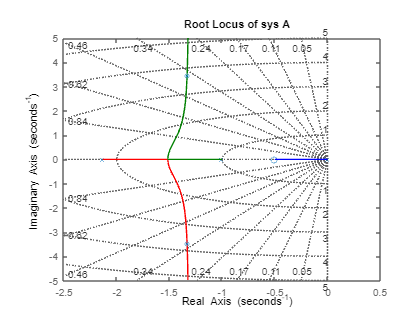


% Root locus plots for systems with phase-lead compensators
% Root locus plot for sys_A
figure;
rlocus(sys_A);
hold on
plot(points, '*');
title('Root Locus of sys A');
xlabel('Real Axis');
ylabel('Imaginary Axis');
grid on; 
hold off

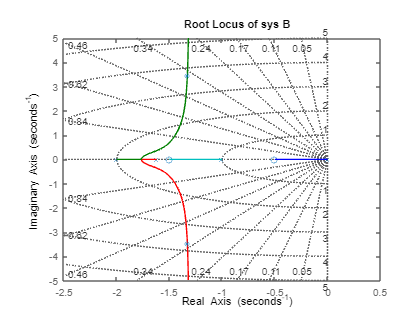


% Root locus plot for sys_B
figure;
rlocus(sys_B);
hold on
plot(points, '*');
title('Root Locus of sys B');
xlabel('Real Axis');
ylabel('Imaginary Axis');
grid on; 
hold off

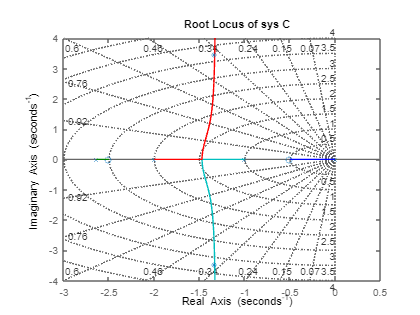


% Root locus plot for sys_C
figure;
rlocus(sys_C);
hold on
plot(points, '*');
title('Root Locus of sys C');
xlabel('Real Axis');
ylabel('Imaginary Axis');
grid on; 
hold off

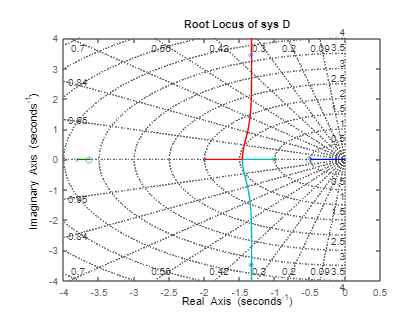


% Root locus plot for sys_D
figure;
rlocus(sys_D);
hold on
plot(points, '*');
title('Root Locus of sys D');
xlabel('Real Axis');
ylabel('Imaginary Axis');
grid on; 
hold off

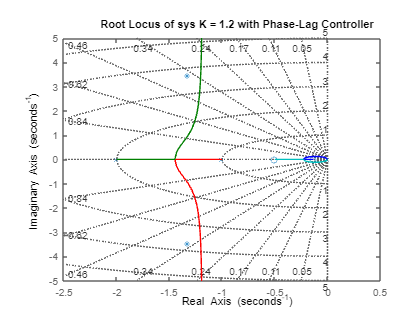


%% Add phase-lag controllers and their root locus plots

% Define systems with added phase-lag controllers
sys_00 = series(tf([1 0.1333], [1 0.0024]), sys_0);
sys_AA = series(tf([1 0.1333], [1 0.0119]), sys_A);
sys_BB = series(tf([1 0.1333], [1 0.0117]), sys_B);
sys_CC = series(tf([1 0.1333], [1 0.0121]), sys_C);
sys_DD = series(tf([1 0.1333], [1 0.0123]), sys_D);

% Root locus plot for sys_00
figure;
rlocus(sys_00);
hold on
plot(points, '*');
title('Root Locus of sys K = 1.2 with Phase-Lag Controller');
xlabel('Real Axis');
ylabel('Imaginary Axis');
grid on; 
hold off

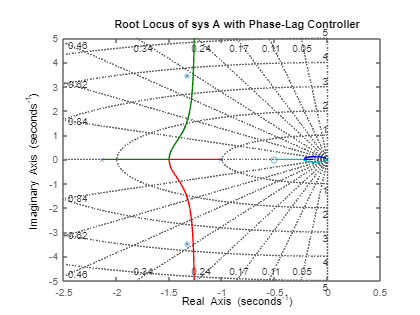


% Root locus plot for sys_AA
figure;
rlocus(sys_AA);
hold on
plot(points, '*');
title('Root Locus of sys A with Phase-Lag Controller');
xlabel('Real Axis');
ylabel('Imaginary Axis');
grid on; 
hold off

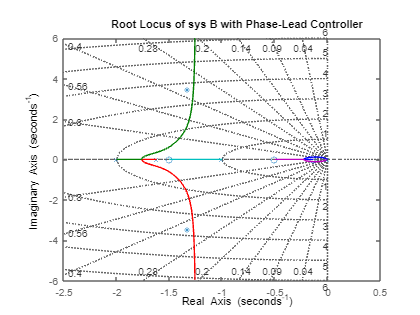


% Root locus plot for sys_BB
figure;
rlocus(sys_BB);
hold on
plot(points, '*');
title('Root Locus of sys B with Phase-Lead Controller');
xlabel('Real Axis');
ylabel('Imaginary Axis');
grid on; 
hold off

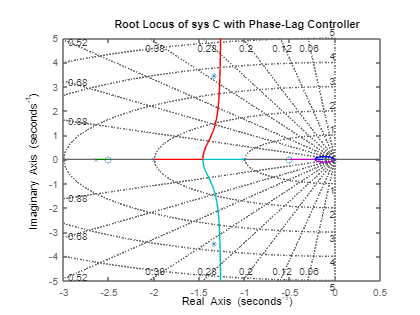


% Root locus plot for sys_CC
figure;
rlocus(sys_CC);
hold on
plot(points, '*');
title('Root Locus of sys C with Phase-Lag Controller');
xlabel('Real Axis');
ylabel('Imaginary Axis');
grid on; 
hold off

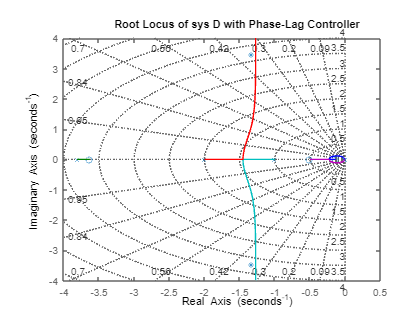


% Root locus plot for sys_DD
figure;
rlocus(sys_DD);
hold on
plot(points, '*');
title('Root Locus of sys D with Phase-Lag Controller');
xlabel('Real Axis');
ylabel('Imaginary Axis');
grid on; 
hold off

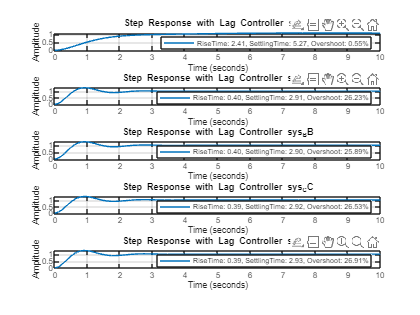


% Create closed-loop systems with unit feedback
cl_sys_00 = feedback(sys_00, 1); % Closed-loop system with initial gain adjustment
cl_sys_AA = feedback(sys_AA, 1); % Closed-loop system with compensator A
cl_sys_BB = feedback(sys_BB, 1); % Closed-loop system with compensator B
cl_sys_CC = feedback(sys_CC, 1); % Closed-loop system with compensator C
cl_sys_DD = feedback(sys_DD, 1); % Closed-loop system with compensator D

% Time vector for simulation
t = 0:0.01:10;

% Compute step responses
[y_00, t_00] = step(cl_sys_00, t);
[y_AA, t_AA] = step(cl_sys_AA, t);
[y_BB, t_BB] = step(cl_sys_BB, t);
[y_CC, t_CC] = step(cl_sys_CC, t);
[y_DD, t_DD] = step(cl_sys_DD, t);

% Compute step response characteristics
info_00 = stepinfo(y_00, t_00);
info_AA = stepinfo(y_AA, t_AA);
info_BB = stepinfo(y_BB, t_BB);
info_CC = stepinfo(y_CC, t_CC);
info_DD = stepinfo(y_DD, t_DD);

% Plot step responses
figure;
subplot(5,1,1);
plot(t_00, y_00);
grid on;
title('Step Response with Lag Controller sys_00');
xlabel('Time (seconds)');
ylabel('Amplitude');
legend(sprintf('RiseTime: %.2f, SettlingTime: %.2f, Overshoot: %.2f%%', info_00.RiseTime, info_00.SettlingTime, info_00.Overshoot));

subplot(5,1,2);
plot(t_AA, y_AA);
grid on;
title('Step Response with Lag Controller sys_AA');
xlabel('Time (seconds)');
ylabel('Amplitude');
legend(sprintf('RiseTime: %.2f, SettlingTime: %.2f, Overshoot: %.2f%%', info_AA.RiseTime, info_AA.SettlingTime, info_AA.Overshoot));

subplot(5,1,3);
plot(t_BB, y_BB);
grid on;
title('Step Response with Lag Controller sys_BB');
xlabel('Time (seconds)');
ylabel('Amplitude');
legend(sprintf('RiseTime: %.2f, SettlingTime: %.2f, Overshoot: %.2f%%', info_BB.RiseTime, info_BB.SettlingTime, info_BB.Overshoot));

subplot(5,1,4);
plot(t_CC, y_CC);
grid on;
title('Step Response with Lag Controller sys_CC');
xlabel('Time (seconds)');
ylabel('Amplitude');
legend(sprintf('RiseTime: %.2f, SettlingTime: %.2f, Overshoot: %.2f%%', info_CC.RiseTime, info_CC.SettlingTime, info_CC.Overshoot));

subplot(5,1,5);
plot(t_DD, y_DD);
grid on;
title('Step Response with Lag Controller sys_DD');
xlabel('Time (seconds)');
ylabel('Amplitude');
legend(sprintf('RiseTime: %.2f, SettlingTime: %.2f, Overshoot: %.2f%%', info_DD.RiseTime, info_DD.SettlingTime, info_DD.Overshoot));

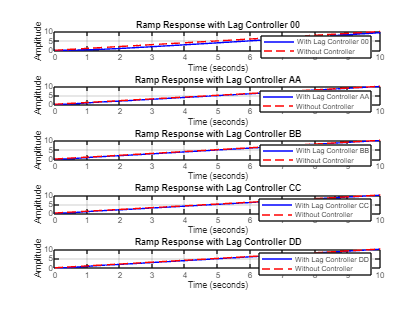


% Time vector for simulation
t = 0:0.01:10;
ramp_input = t; % Ramp input signal over time 't'

% Ramp response for cl_sys_00 (Lag Controller)
[y_r_00, t_r_00] = lsim(cl_sys_00, ramp_input, t); 
[y_r_00_sys, t_r_00_sys] = lsim(sys_0, ramp_input, t); 
figure;
subplot(5,1,1);
plot(t_r_00, y_r_00, 'b', t_r_00_sys, ramp_input, 'r--'); % Plot ramp response for cl_sys_00
legend('With Lag Controller 00', 'Without Controller');
grid on;
title('Ramp Response with Lag Controller 00');
xlabel('Time (seconds)');
ylabel('Amplitude');

% Ramp response for cl_sys_AA (Lag Controller)
[y_r_AA, t_r_AA] = lsim(cl_sys_AA, ramp_input, t); 
[y_r_AA_sys, t_r_AA_sys] = lsim(sys_A, ramp_input, t); 
subplot(5,1,2);
plot(t_r_AA, y_r_AA, 'b', t_r_AA_sys, ramp_input, 'r--'); % Plot ramp response for cl_sys_AA
legend('With Lag Controller AA', 'Without Controller');
grid on;
title('Ramp Response with Lag Controller AA');
xlabel('Time (seconds)');
ylabel('Amplitude');

% Ramp response for cl_sys_BB (Lag Controller)
[y_r_BB, t_r_BB] = lsim(cl_sys_BB, ramp_input, t); 
[y_r_BB_sys, t_r_BB_sys] = lsim(sys_B, ramp_input, t); 
subplot(5,1,3);
plot(t_r_BB, y_r_BB, 'b', t_r_BB_sys, ramp_input, 'r--'); % Plot ramp response for cl_sys_BB
legend('With Lag Controller BB', 'Without Controller');
grid on;
title('Ramp Response with Lag Controller BB');
xlabel('Time (seconds)');
ylabel('Amplitude');

% Ramp response for cl_sys_CC (Lag Controller)
[y_r_CC, t_r_CC] = lsim(cl_sys_CC, ramp_input, t); 
[y_r_CC_sys, t_r_CC_sys] = lsim(sys_C, ramp_input, t); 
subplot(5,1,4);
plot(t_r_CC, y_r_CC, 'b', t_r_CC_sys, ramp_input, 'r--'); % Plot ramp response for cl_sys_CC
legend('With Lag Controller CC', 'Without Controller');
grid on;
title('Ramp Response with Lag Controller CC');
xlabel('Time (seconds)');
ylabel('Amplitude');

% Ramp response for cl_sys_DD (Lag Controller)
[y_r_DD, t_r_DD] = lsim(cl_sys_DD, ramp_input, t); 
[y_r_DD_sys, t_r_DD_sys] = lsim(sys_D, ramp_input, t); 
subplot(5,1,5);
plot(t_r_DD, y_r_DD, 'b', t_r_DD_sys, ramp_input, 'r--'); % Plot ramp response for cl_sys_DD
legend('With Lag Controller DD', 'Without Controller');
grid on;
title('Ramp Response with Lag Controller DD');
xlabel('Time (seconds)');
ylabel('Amplitude');